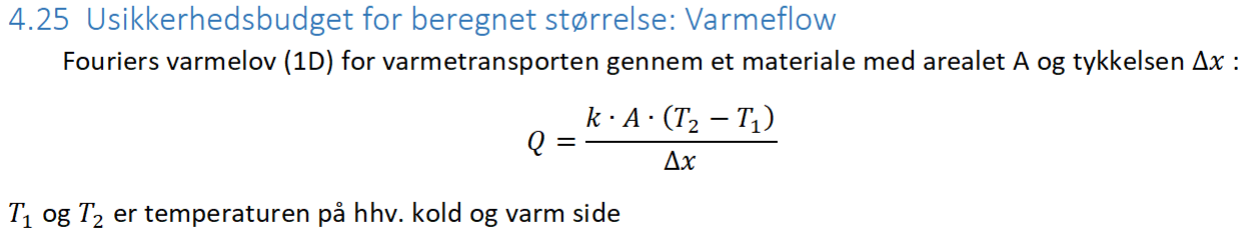

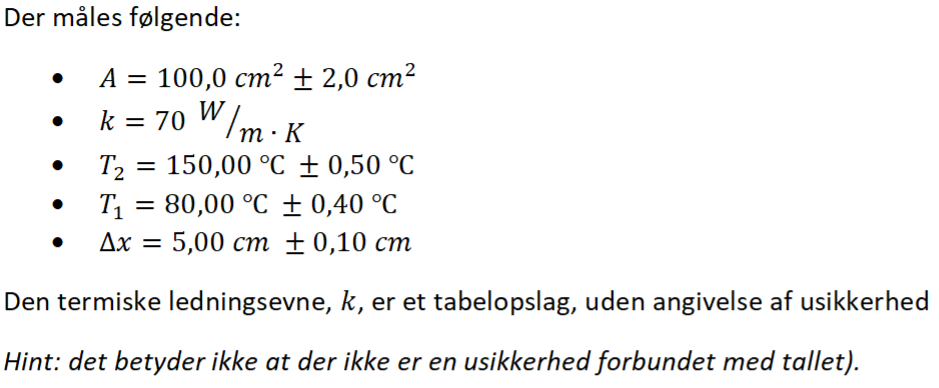

### A.

Argumenter for fordelingstype for hvert enkelt bidrag

Hint: Der er ikke nogen rigtige eller forkerte svar, men antagelse og argument skal passe sammen – forsøg at benytte alle fordelingstyper (hvis du digter lidt)?

Målingerne på vores **areal** **A** kan ses som **trekants fordelt** vi kan forstille os der er lavet to firkantfordelte målinger for at afgøre arealet.

Dette kunne være siderne $l_1$ og $l_2$ eller længde og radius af et rør.

Den **termiske ledning k** kan ses som en normalfordeling med lille spredning da den nok er lavet af mange præcise målinger af et labratorie. Vi ser den derfor bare **uden usikkerhed**.

**Temperatur målingerne **$T_1$  og $T_2$ kunne være **firkant fordelt** hvis man ser dem som digitale termometre der har en indbyggede fejl der tilfældigt lægger et tal $\pm u$ til målingen

Vi ser  $\Delta x$ som **U fordelt** da vi kan have en lille markering på målepinden der hvor den præcise måling er, hvilket besværliggøre en fuldstændig præcis måling.

### B.

Beregn standardusikkerheden under ovenstående antagelser?

Bemærk: Bemærk at resultatet afhænger af dine valg i A, så forskellige resultater kan være rigtige

clear
A = 100 /100 / 100; % m^2
a_A = 2 / 100 / 100;
u_A = a_A/sqrt(6) %trekant fordelt

u_A = 8.1650e-05

k = 70; % W/(m*K)
a_k = 0;
u_k = 0 % nok mere præcist normalt fordelt med en udregnede spredning som er usikkerheden.

u_k = 0

T_1 = 80 + 273.15; % K
a_T_1 = 0.40;
u_T_1 = a_T_1/sqrt(3) %firkant fordelt

u_T_1 = 0.2309

T_2 = 150 + 273.15; % K
a_T_2 = 0.50;
u_T_2 = a_T_2/sqrt(3) %firkantfordelt

u_T_2 = 0.2887

Delta_x = 5 /100 ; % m
a_Delta_x = 0.10 /100;
u_Delta_x = a_Delta_x/sqrt(3) %U fordelt

u_Delta_x = 5.7735e-04

Q = k * A * (T_2 - T_1) / Delta_x

Q = 980.0000

A*(T_1-T_2) / Delta_x * u_Delta_x^2

ans = -4.6667e-06

### C.

Opstil usikkerhedsberegningen i excel. Sørg for at lave en skalerbar opstilling (hvor antallet af usikkerhedskomponenter nemt kan øges/reduceres)

syms A k T_1 T_2 Delta_x
f = k * A * (T_2 - T_1) / Delta_x;
vars_and_u = [[A, 100 /100 / 100, u_A]; 
              [k, 70, u_k];
              [T_1, 80, u_T_1];
              [T_2, 150, u_T_2];
              [Delta_x, 5 /100, u_Delta_x]
              ];
vars_and_u(:,1), vars_and_u(:,2), vars_and_u(:,3)

$$ans = \left(\begin{array}{c} A\\ k\\ T_{1}\\ T_{2}\\ \Delta_{x} \end{array}\right)$$

$$ans = \left(\begin{array}{c} \frac{1}{100}\\ 70\\ 80\\ 150\\ \frac{1}{20} \end{array}\right)$$

$$ans = \left(\begin{array}{c} \frac{6024681386173057}{73786976294838206464}\\ 0\\ \frac{2\,\sqrt{3}}{15}\\ \frac{\sqrt{3}}{6}\\ \frac{1331279082078543}{2305843009213693952} \end{array}\right)$$

op = vpa(STAT.Ophobningsloven(f,vars_and_u(:,1), vars_and_u(:,2), vars_and_u(:,3)), 8)

$$ds = \left(\begin{array}{ccccc} -\frac{k\,\left(T_{1}-T_{2}\right)}{\Delta_{x}} & \frac{A\,k\,\left(T_{1}-T_{2}\right)}{{\Delta_{x}}^{2}} & -\frac{A\,k}{\Delta_{x}} & \frac{A\,k}{\Delta_{x}} & -\frac{A\,\left(T_{1}-T_{2}\right)}{\Delta_{x}} \end{array}\right)$$

$$final = \frac{1361696604961955598028167976458169515625}{21267647932558653966460912964485513216}$$

$$ans = 64.03$$

$$final = \left(\begin{array}{cc} \frac{1361696604961955598028167976458169515625}{21267647932558653966460912964485513216} & 0 \end{array}\right)$$

$$ans = 0.0$$

$$final = \left(\begin{array}{ccc} \frac{1361696604961955598028167976458169515625}{21267647932558653966460912964485513216} & 0 & \frac{784}{75} \end{array}\right)$$

$$ans = 10.45$$

$$final = \left(\begin{array}{cccc} \frac{1361696604961955598028167976458169515625}{21267647932558653966460912964485513216} & 0 & \frac{784}{75} & \frac{49}{3} \end{array}\right)$$

$$ans = 16.33$$

$$final = \left(\begin{array}{ccccc} \frac{1361696604961955598028167976458169515625}{21267647932558653966460912964485513216} & 0 & \frac{784}{75} & \frac{49}{3} & \frac{86842895724614513464179829139601}{1329227995784915872903807060280344576} \end{array}\right)$$

$$ans = 6.533e-5$$

$$op = 9.5296064$$


bidrag_sum = 0;

for i = 1:length(vars_and_u)
    f_new = f;

    for j = 1:length(vars_and_u)
        if i ~= j
            f_sub = subs(f_new, vars_and_u(j,1), vars_and_u(j,2));
            f_new = f_sub;
        end
    end
    
    diff_f = diff(f_new, vars_and_u(i,1))

    bidrag = (subs(diff_f, vars_and_u(i,1), vars_and_u(i,2)) * vars_and_u(i,3))^2;

    bidrag_sum = bidrag + bidrag_sum;
    vpa(bidrag)
end

$$diff\_f = 98000$$

$$ans = 64.026666666666675133465525982517$$

$$diff\_f = 14$$

$$ans = 0.0$$

$$diff\_f = -14$$

$$ans = 10.453333333333333333333333333333$$

$$diff\_f = 14$$

$$ans = 16.333333333333333333333333333333$$

$$diff\_f = -\frac{49}{{\Delta_{x}}^{2}}$$

$$ans = 128.05333333333334773634296428535$$

bidrag_final = sqrt(bidrag_sum);
vpa(bidrag_final,3)

$$ans = 14.8$$

Q

Q = 980.0000



%     bidrag_sum = bidrag + bidrag_sum

% function [y, y_u] = ophobningsloven(f, vars_and_u)
% 
% bidrag_sum = 0;
% 
% for i = 1:length(vars_and_u)
% 
%     for j = 1:length(vars_and_u) 
%         if 1 ~= j 
%             f_sub = subs(f, vars_and_u(j,1), vars_and_u(j,2));
%         end
%     f = f_sub
%     end
% 
%     bidrag = sqrt((diff(f_sub, vars_and_u(i,2)) * vars_and_u(i,3))^2)
% 
%     bidrag_sum = bidrag + bidrag_sum
% end
% 
% [y, y_u]
% end